# `Compare and Contrast (CnC) Code X`

`Using Test Data ``OUTSIDE`` Training Boundaries`

% Housekeeping
clc;
clear;
close all;

% Load State Space Model
load('syys.mat');
load('ssest.mat');
load('C.mat');
load('K_aug.mat')
load_system('MainSim.slx');

Kp      = K_aug(1:5,1:9);
Ki      = K_aug(1:5,10:14);

#### `Inputs`

% Define simulation parameters
simtime     = 10000;  % Total simulation time in seconds
numsamples  = 100000; % Total number of samples
step        = 100;    % Step duration

% Calculate the sample time and create the time vector
sampletime  = simtime / numsamples;           % Sample time for each step
t           = (0:numsamples-1) * sampletime;  % Time vector

% Step input signals
u = zeros(numsamples, 5);

% Step inputs for u-velocity
u(t >= 1*step, 1) = 0.7

u =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


% u(t >= 1*step, 1)   = -0.7;      
% u(t >= 90*step, 1)  = -2;

% Inputs for Gamma
u(t >= 20*step, 2) = 0.261799;
% u(t >= 45*step, 2) = 0.15708;
u(t >= 50*step, 2) = 0.20944;
% u(t >= 85*step, 2) = 0;

% Inputs for Beta
u(t >= 0.5*step, 3) = 0.0872665;
% u(t >= 50*step, 3) = -0.0523599;
u(t >= 85*step, 3) = -0.06;

% Step inputs for Phi
u(t >= 0.1*step, 4)  = 0;
% u(t >= 65*step, 4)  = 0;    
%u(t >= 70*step, 4)  = 0;    

% Step inputs for Psi
u(t >= 0.1*step, 5)  = 0;
% u(t >= 80*step, 5)  = 0;     
% u(t >= 85*step, 5)  = -0.07;  

#### `Convert Data to Timeseries`

% Convert Data to Timeseries
% Use the same time vector `t`
refinputs                   = timeseries(u, t(:)); % Use `u` as data
refinputs.Name              = 'Reference Inputs';
refinputs.TimeInfo.Units    = 'seconds';

#### `Run Simulink`

% Set the solver type to fixed-step and use Runge-Kutta method
set_param('MainSim', 'Solver', 'FixedStepDiscrete'); % Use FixedStepDiscrete solver

% Set the fixed step size
set_param('MainSim', 'FixedStep', '0.1');

% Set the solver algorithm to a Runge-Kutta method (e.g., ode4)
set_param('MainSim', 'Solver', 'ode4'); % Fixed-step Runge-Kutta solver

sim('MainSim.slx');

# `PLOTS`

`Figures Folder`

figFolder = 'Figures_CnC';
if ~exist(figFolder, 'dir')
    mkdir(figFolder);
end

#### `States`

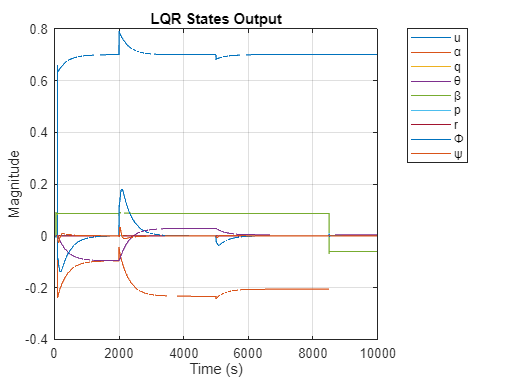

state_names = {'u', 'α', 'q', 'θ', 'β', 'p', 'r', 'Φ', 'ψ'};

figure(1);
plot(xstate.Time, xstate.Data);
xlabel('Time (s)');
ylabel('Magnitude');
title('LQR States Output');
legend(state_names, 'location', 'northeastoutside');
grid on;
saveas(gcf, fullfile(figFolder, 'LQRStatesOutPSI3.png'));

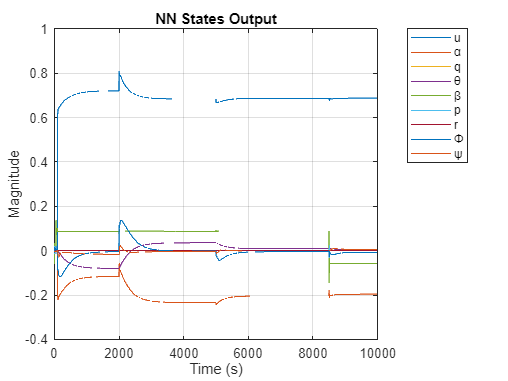


LQRxstateM = xstate.data;
LQRxstateM = LQRxstateM(1:end-1, :);

figure(2);
plot(NNxout.Time, NNxout.Data);
xlabel('Time (s)');
ylabel('Magnitude');
title('NN States Output');
legend(state_names, 'location', 'northeastoutside');
grid on;
saveas(gcf, fullfile(figFolder, 'NNStatesOutPSI3.png'));


NNxstateM = NNxout.data;
NNxstateM = NNxstateM(1:end-1, :);

#### `Controller`

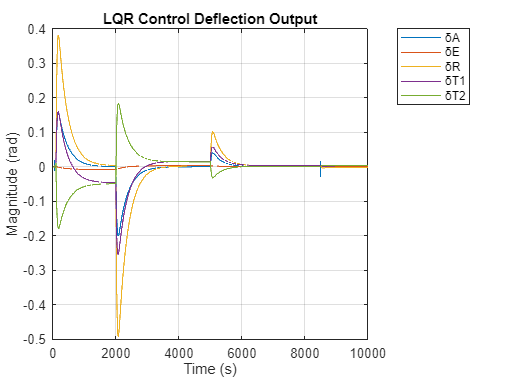

control_names = {'δA', 'δE', 'δR', 'δT1', 'δT2'};

figure(3);
plot(controlout.Time, controlout.Data);
xlabel('Time (s)');
ylabel('Magnitude (rad)');
title('LQR Control Deflection Output');
legend(control_names, 'location', 'northeastoutside');
grid on;
saveas(gcf, fullfile(figFolder, 'PSIControlOut3.png'));

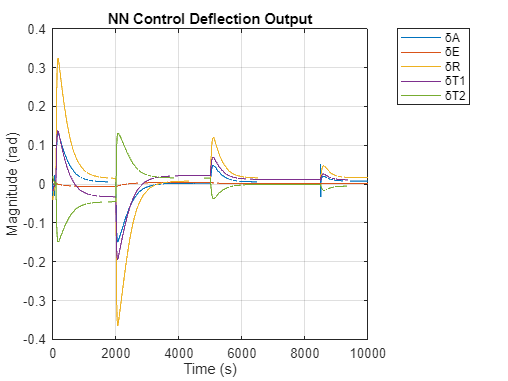


LQRcontrolM = controlout.data;
LQRcontrolM = LQRcontrolM(1:end-1, :);

figure(4);
plot(NNcout.Time, NNcout.Data);
xlabel('Time (s)');
ylabel('Magnitude (rad)');
title('NN Control Deflection Output');
legend(control_names, 'location', 'northeastoutside');
grid on;
saveas(gcf, fullfile(figFolder, 'PSINNcout3.png'));


NNcontrolM = NNcout.data;
NNcontrolM = NNcontrolM(1:end-1, :);

#### `Tracked`

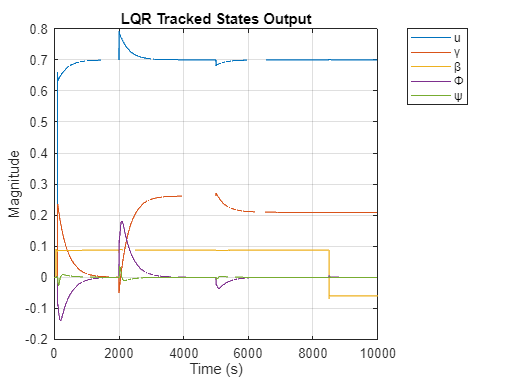

tracked_names = {'u', 'γ', 'β', 'Φ', 'ψ'};

figure(5);
plot(trackedstate.Time, trackedstate.Data);
xlabel('Time (s)');
ylabel('Magnitude');
title('LQR Tracked States Output');
legend(tracked_names, 'location', 'northeastoutside');
grid on;
saveas(gcf, fullfile(figFolder, 'PSITrackedStates3.png'));

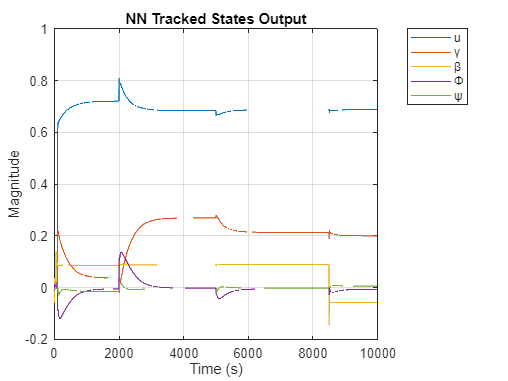


LQRtrackedM = trackedstate.data;
LQRtrackedM = LQRtrackedM(1:end-1, :);

figure(6);
plot(NNtrckd.Time, NNtrckd.Data);
xlabel('Time (s)');
ylabel('Magnitude');
title('NN Tracked States Output');
legend(tracked_names, 'location', 'northeastoutside');
grid on;
saveas(gcf, fullfile(figFolder, 'PSINNtrckd3.png'));


NNtrackedM = NNtrckd.Data;
NNtrackedM = NNtrackedM(1:end-1, :);

#### `Data Prep Controller Outputs`

NetOut = NNcout.Data;            % NN Data
NetOut = NetOut(1:end-1, :);
LQROut = controlout.Data;       % LQR Data
LQROut = LQROut(1:end-1, :);

#### `CnC Plots of Controller Outputs`

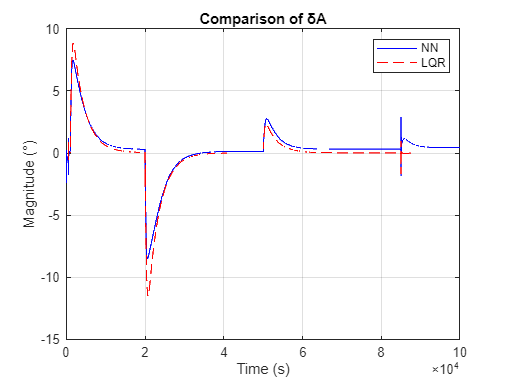

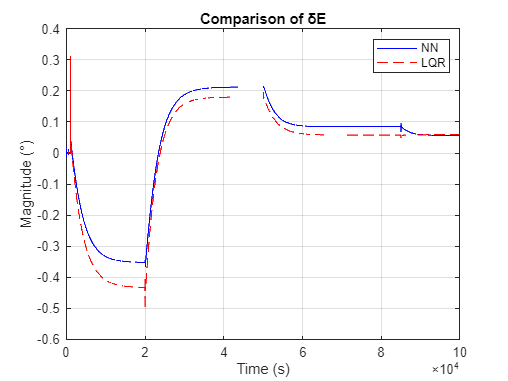

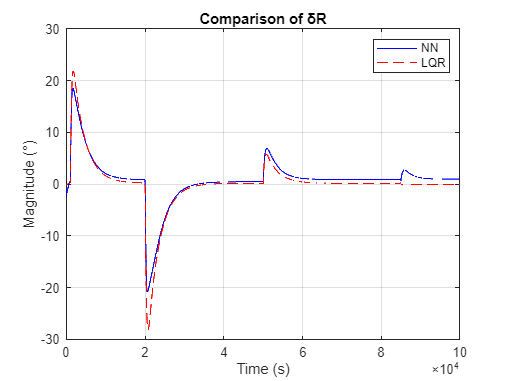

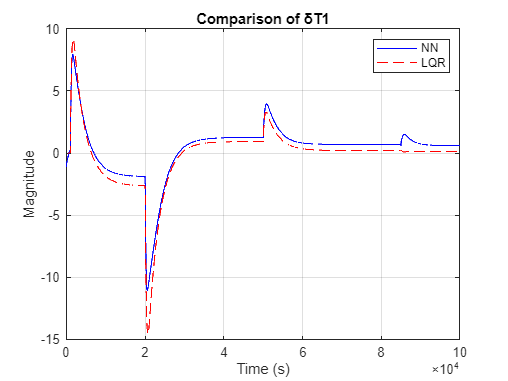

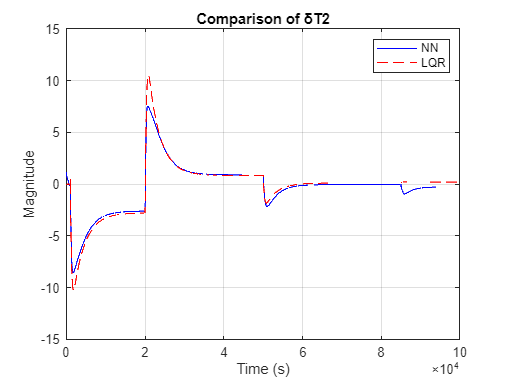

% Conversion factor from radians to degrees
radToDeg = 180 / pi;

% Plot each output from NetOut
numVariables = size(NetOut, 2); % Number of columns (variables) in NetOut

for i = 1:numVariables
    figure;
    if i <= numVariables - 2
        % Convert data from radians to degrees for the first variables
        plot(NetOut(:, i) * radToDeg, 'b', 'DisplayName', 'NN');
        hold on;
        plot(LQROut(:, i) * radToDeg, 'r--', 'DisplayName', 'LQR');
        ylabel('Magnitude (°)');
    else
        % Do not convert the last two variables
        plot(NetOut(:, i) * radToDeg, 'b', 'DisplayName', 'NN');
        hold on;
        plot(LQROut(:, i) * radToDeg, 'r--', 'DisplayName', 'LQR');
        ylabel('Magnitude');
    end
    title(sprintf('Comparison of %s', control_names{i})); % Use variable name in title
    xlabel('Time (s)');
    legend('NN', 'LQR');
    grid on;

    % Save each figure as a PNG file
    saveas(gcf, fullfile(figFolder, sprintf('PSICnC3_%s.png', control_names{i})));
end


% Save each column of NetOut separately
for i = 1:numVariables
    if i <= numVariables - 2
        % Convert to degrees and save for the first variables
        assignin('base', sprintf('NetOut3_Column%d', i), NetOut(:, i) * radToDeg);
    else
        % Save without conversion for the last two variables
        assignin('base', sprintf('NetOut3_Column%d', i), NetOut(:, i));
    end
end

% Save each column of LQROut separately
for i = 1:numVariables
    if i <= numVariables - 2
        % Convert to degrees and save for the first variables
        assignin('base', sprintf('LQROut3_Column%d', i), LQROut(:, i) * radToDeg);
    else
        % Save without conversion for the last two variables
        assignin('base', sprintf('LQROut3_Column%d', i), LQROut(:, i));
    end
end

#### `Data Prep State Outputs`

NetOutx = NNxout.Data;          % NN Data
NetOutx = NetOutx(1:end-1, :);
LQROutx = xstate.Data;           % LQR Data
LQROutx = LQROutx(1:end-1, :);

#### `CnC Plots of State Outputs`

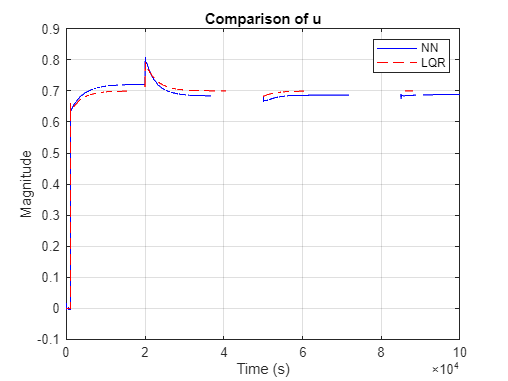

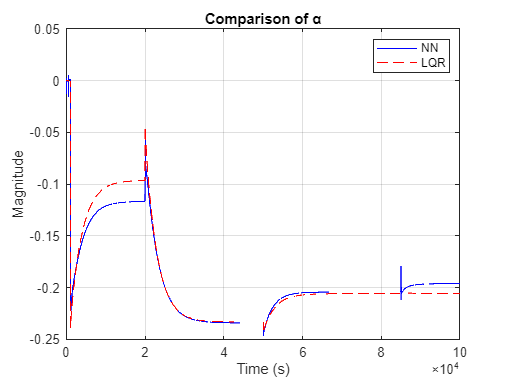

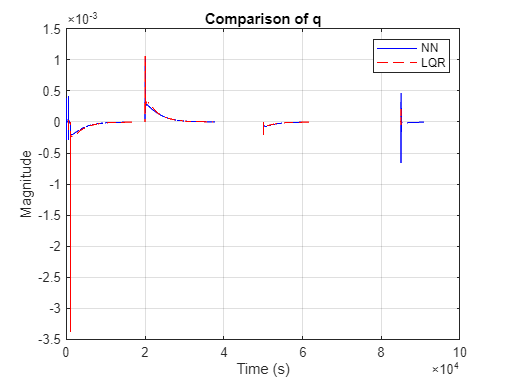

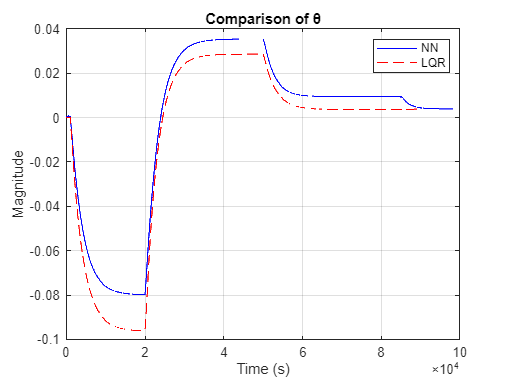

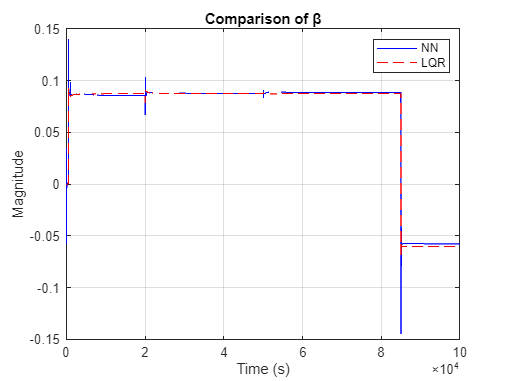

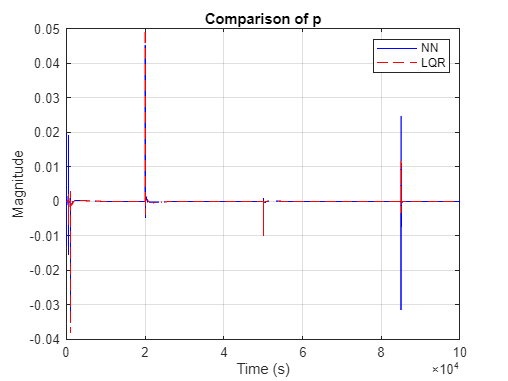

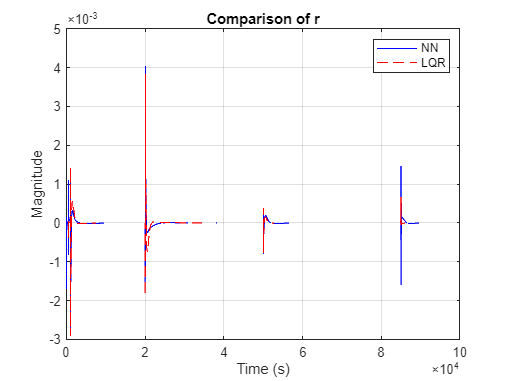

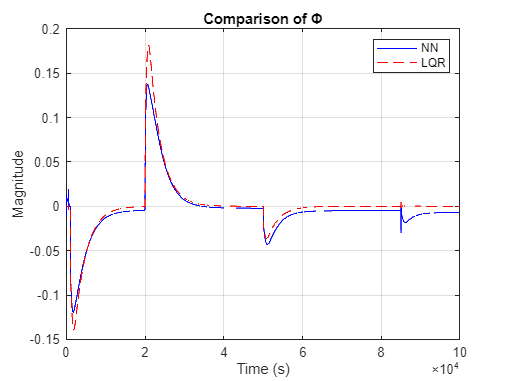

sn = {'u', 'Alpha', 'q', 'Theta', 'Beta', 'p', 'r', 'Phi', 'Psi'};
% Plot each output from NetOut
numVariables = size(NetOutx, 2); % Number of columns (variables) in NetOut

for i = 1:numVariables
    figure;
    plot(NetOutx(:, i), 'b', 'DisplayName', 'NN');
    hold on;
    plot(LQROutx(:, i), 'r--', 'DisplayName', 'LQR');
    title(sprintf('Comparison of %s', state_names{i})); % Use variable name in title
    xlabel('Time (s)');
    ylabel('Magnitude');
    legend('NN', 'LQR');
    grid on;

    % Save each figure as a PNG file
    saveas(gcf, fullfile(figFolder, sprintf('PSICnC3_%s.png', state_names{i})));
end


% Save each column of NetOut separately
for i = 1:size(NetOutx, 2)
    assignin('base', sprintf('NetOutx3_Column%d', i), NetOutx(:, i));
end

% Save each column of LQROut separately
for i = 1:size(LQROutx, 2)
    assignin('base', sprintf('LQROutx3_Column%d', i), LQROutx(:, i));
end

#### `Data Prep Tracked Outputs (Gamma Only)`

NetOuttr = NNtrckd.Data;            % NN Data
NetOuttr = NetOuttr(1:end-1, :);         
LQROuttr = trackedstate.Data;       % LQR Data
LQROuttr = LQROuttr(1:end-1, :);

#### `CnC Plots of Tracked Outputs (Converted)`

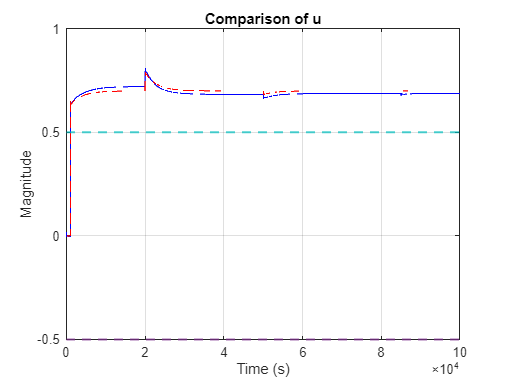

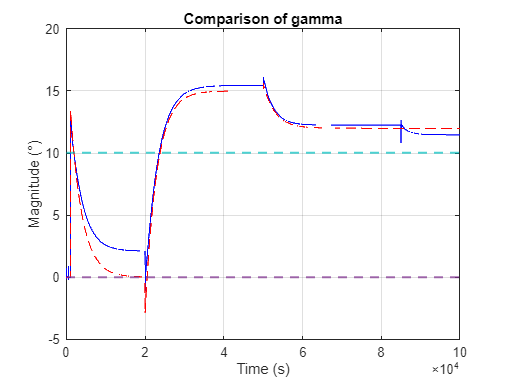

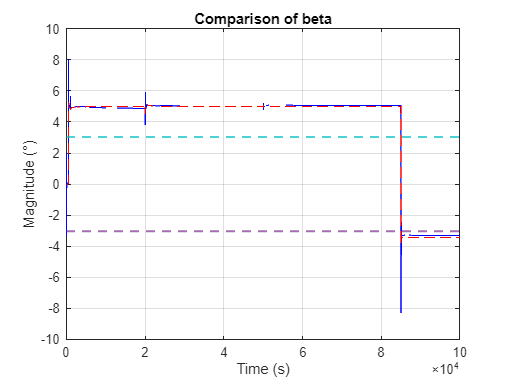

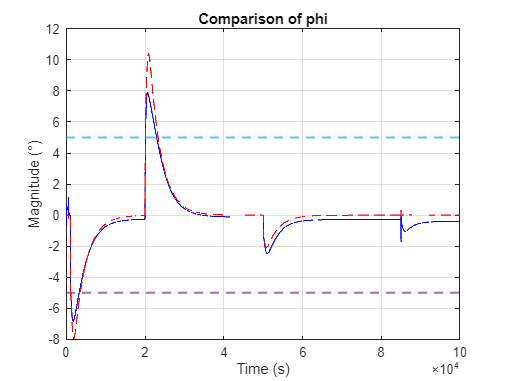

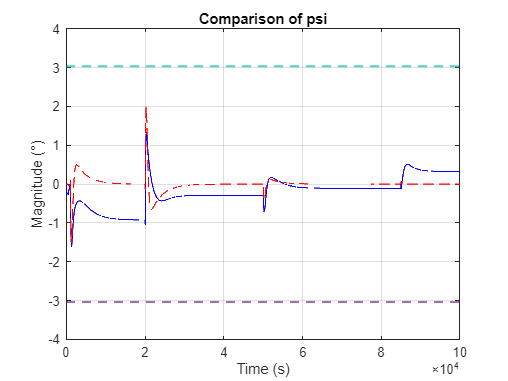

% Conversion factor from radians to degrees
radToDeg = 180 / pi;

% Array of tracked names for labeling
tracked_names = {'u', 'gamma', 'beta', 'phi', 'psi'}; 
tn = {'u', 'Gamma', 'Beta', 'Phi', 'Psi'}; 
% Specify boundaries for each variable
lower_bounds = [-0.5, 0, -0.053, -0.0873, -0.053];  % Example lower boundaries
upper_bounds = [0.5, 0.1750, 0.053, 0.0873, 0.053];  % Example upper boundaries

% Determine the number of columns (variables) to plot
numVariables = size(NetOuttr, 2); 

% Loop through each column to plot and save them
for i = 1:numVariables
    figure;
    % Convert angles to degrees if not the first variable
    if i > 1
        plot(NetOuttr(:, i) * radToDeg, 'b', 'DisplayName', 'NN');
        hold on;
        plot(LQROuttr(:, i) * radToDeg, 'r--', 'DisplayName', 'LQR');
        yline(lower_bounds(i) * radToDeg, 'Color', [0.4940, 0.1840, 0.5560], 'LineStyle', '--', 'LineWidth', 1.5); % Magenta
        yline(upper_bounds(i) * radToDeg, 'Color', [0, 0.75, 0.75], 'LineStyle', '--', 'LineWidth', 1.5); % Cyan
        ylabel('Magnitude (°)');
    else
        plot(NetOuttr(:, i), 'b', 'DisplayName', 'NN');
        hold on;
        plot(LQROuttr(:, i), 'r--', 'DisplayName', 'LQR');
        yline(lower_bounds(i), 'Color', [0.4940, 0.1840, 0.5560], 'LineStyle', '--', 'LineWidth', 1.5); % Magenta
        yline(upper_bounds(i), 'Color', [0, 0.75, 0.75], 'LineStyle', '--', 'LineWidth', 1.5); % Cyan
        ylabel('Magnitude');
    end
    
    title(sprintf('Comparison of %s', tracked_names{i})); % Use variable name in title
    xlabel('Time (s)');
    grid on;

    % Save each figure as a PNG file
    % Save each figure as a PNG file
    saveas(gcf, fullfile(figFolder, sprintf('PSICnC3_%s.png', tracked_names{i})));

    % Save each column of NetOut separately
    assignin('base', sprintf('NetOuttr3_%s', tn{i}), NetOuttr(:, i));

    % Save each column of LQROut separately
    assignin('base', sprintf('LQROuttr3_%s', tn{i}), LQROuttr(:, i));
end

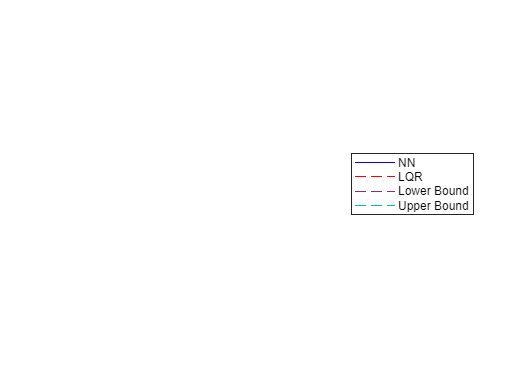


% Create a single figure for the legend
figure;
h1 = plot(NaN, NaN, 'b', 'DisplayName', 'NN');
hold on;
h2 = plot(NaN, NaN, 'r--', 'DisplayName', 'LQR');
h3 = plot(NaN, NaN, 'Color', [0.4940, 0.1840, 0.5560], 'LineStyle', '--', 'LineWidth', 0.5, 'DisplayName', 'Lower Bound'); % Magenta
h4 = plot(NaN, NaN, 'Color', [0, 0.75, 0.75], 'LineStyle', '--', 'LineWidth', 0.5, 'DisplayName', 'Upper Bound'); % Cyan
legend('Location', 'eastoutside'); % Adjust the location as needed
axis off; % Hide the axes for the legend-only plot

% Save the legend figure
saveas(gcf, fullfile(figFolder, 'PSICnC3_Legend.png'))